% 定义差分方程的系数
b = [1 -0.3]; % 差分方程的分子系数
a = [1 -0.5]; % 差分方程的分母系数

% 使用tf()函数创建系统
sys1 = tf(b, a, 1); % 1表示采样时间为1

% 显示系统
disp(sys1);

  tf - 属性:

       Numerator: {[1 -0.3000]}
     Denominator: {[1 -0.5000]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




lww=1;
N=5000;
p=100;

w=sqrt(lww)*randn(N,p);
k=(0:1:N-1);

for j=1:p
    [y(:,j),k]=lsim(sys1,w(:,j),k);
    cov_wy(:,j)=xcov(w(:,j),y(:,j),10,'coeff');
    cov_yw(:,j)=xcov(y(:,j),w(:,j),10,'coeff');
    cov_ww(:,j)=xcov(w(:,j),w(:,j),10,'coeff');
    cov_yy(:,j)=xcov(y(:,j),y(:,j),10,'coeff');
end
m_cov_wy = mean(cov_wy')

m_cov_wy =     0.0017    0.0007    0.0011    0.0029    0.0055    0.0125    0.0238    0.0472    0.0981    0.1938    0.9744   -0.0010    0.0006   -0.0016   -0.0003    0.0004   -0.0006   -0.0000   -0.0002    0.0004    0.0014


m_cov_yw = mean(cov_yw')

m_cov_yw =     0.0014    0.0004   -0.0002   -0.0000   -0.0006    0.0004   -0.0003   -0.0016    0.0006   -0.0010    0.9744    0.1938    0.0981    0.0472    0.0238    0.0125    0.0055    0.0029    0.0011    0.0007    0.0017


m_cov_ww = mean(cov_ww')

m_cov_ww =     0.0014    0.0001   -0.0003   -0.0000   -0.0006    0.0005   -0.0003   -0.0016    0.0010   -0.0010    1.0000   -0.0010    0.0010   -0.0016   -0.0003    0.0005   -0.0006   -0.0000   -0.0003    0.0001    0.0014


m_cov_yy = mean(cov_yy')

m_cov_yy =     0.0019    0.0012    0.0015    0.0032    0.0061    0.0136    0.0263    0.0522    0.1079    0.2141    1.0000    0.2141    0.1079    0.0522    0.0263    0.0136    0.0061    0.0032    0.0015    0.0012    0.0019


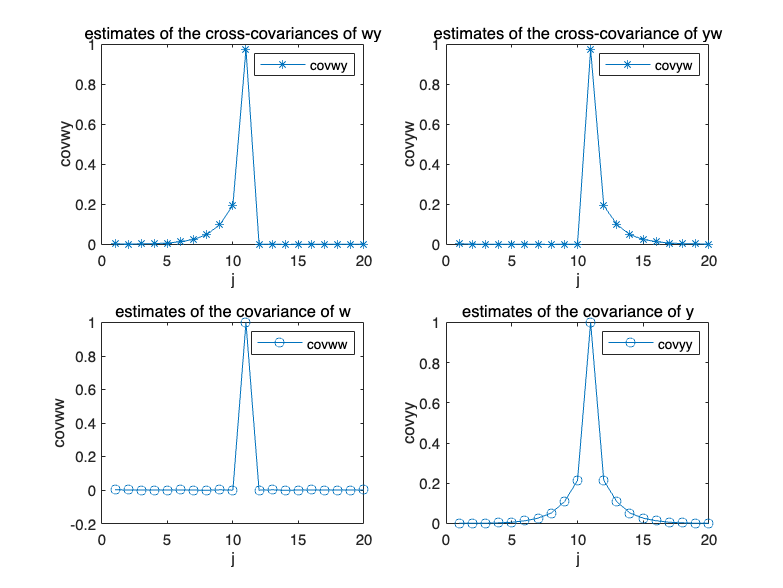


% figure()
% plot(cov_wy(:,2),'-o')


figure()
subplot(2, 2, 1);
plot(m_cov_wy,'-*')
xlabel('j');
ylabel('covwy');
title('estimates of the cross-covariances of wy');
legend('covwy');
xlim([0 20])
%ylim([0 1])

subplot(2, 2, 2);
plot(m_cov_yw,'-*')
xlabel('j');
ylabel('covyw');
title('estimates of the cross-covariance of yw');
legend('covyw');
xlim([0 20])
%ylim([0 1])

subplot(2, 2, 3);
plot(m_cov_ww,'-o')
xlabel('j');
ylabel('covww');
title('estimates of the covariance of w');
legend('covww');
xlim([0 20])
%ylim([0 1])

subplot(2, 2, 4);
plot(m_cov_yy,'-o')
hold off
xlabel('j');
ylabel('covyy');
title('estimates of the covariance of y');
legend('covyy');
xlim([0 20])

%ylim([0 1])

l = -10:10; % 定义时间序列范围为-5到5
f_cov_yw = zeros(size(l)); % 创建一个和l相同大小的零向量
f_cov_wy = zeros(size(l));

%定义冲激序列
delta = dirac(l);
idx = delta == inf;         %idx是逻辑矩阵，将y向量中的每一个元素与inf做比较后得到一个维数与y相同的逻辑矩阵idx，元素与inf相等的位置为逻辑1，不等的其他位置为逻辑0
delta(idx) = 1;  


% 对于l >= 0，计算f_cov_yw(l)
f_cov_yw(l >= 0) = 0.4 * (0.5) .^ l(l >= 0);
f_cov_yw = f_cov_yw + 0.6*delta

f_cov_yw =          0         0         0         0         0         0         0         0         0         0    1.0000    0.2000    0.1000    0.0500    0.0250    0.0125    0.0063    0.0031    0.0016    0.0008    0.0004



% 对于l >= 0，计算f_cov_wy(l)
l_=-l;
f_cov_wy(l <= 0) = 0.4 * (0.5) .^ l_(l_ >= 0);
f_cov_wy = f_cov_wy + 0.6*delta

f_cov_wy =     0.0004    0.0008    0.0016    0.0031    0.0063    0.0125    0.0250    0.0500    0.1000    0.2000    1.0000         0         0         0         0         0         0         0         0         0         0


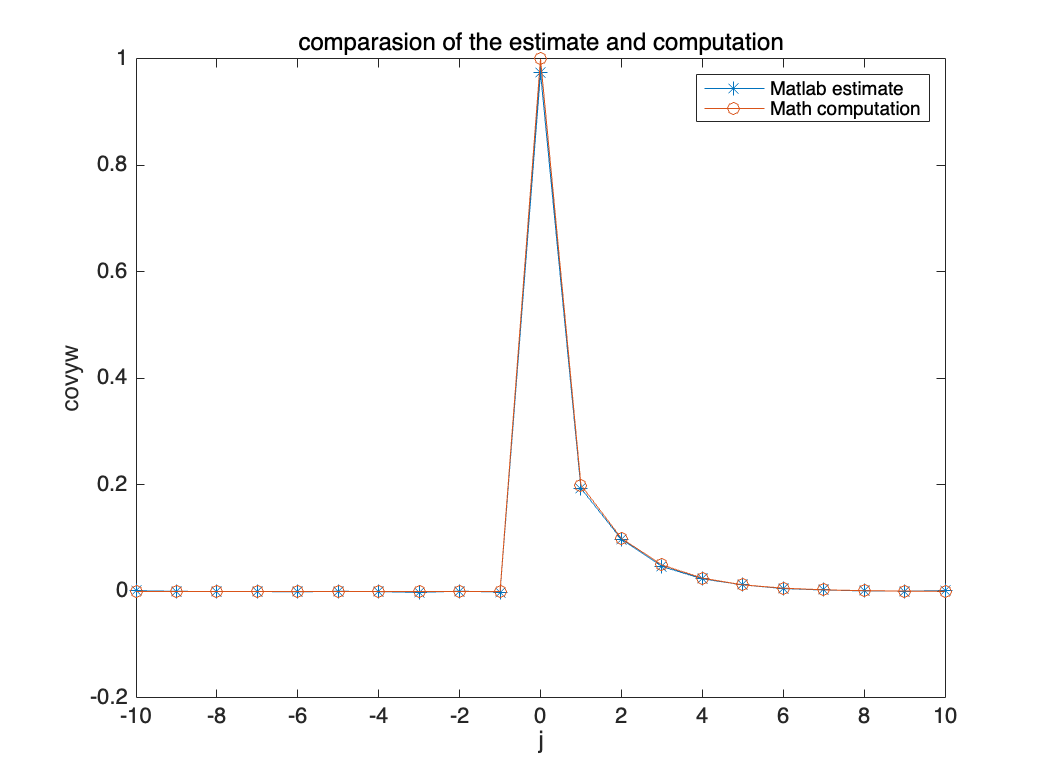



figure()
plot(l,m_cov_yw,'-*')
hold on
plot(l,f_cov_yw,'-o')
legend('Matlab estimate','Math computation');
xlabel('j');
ylabel('covyw');
title('comparasion of the estimate and computation');

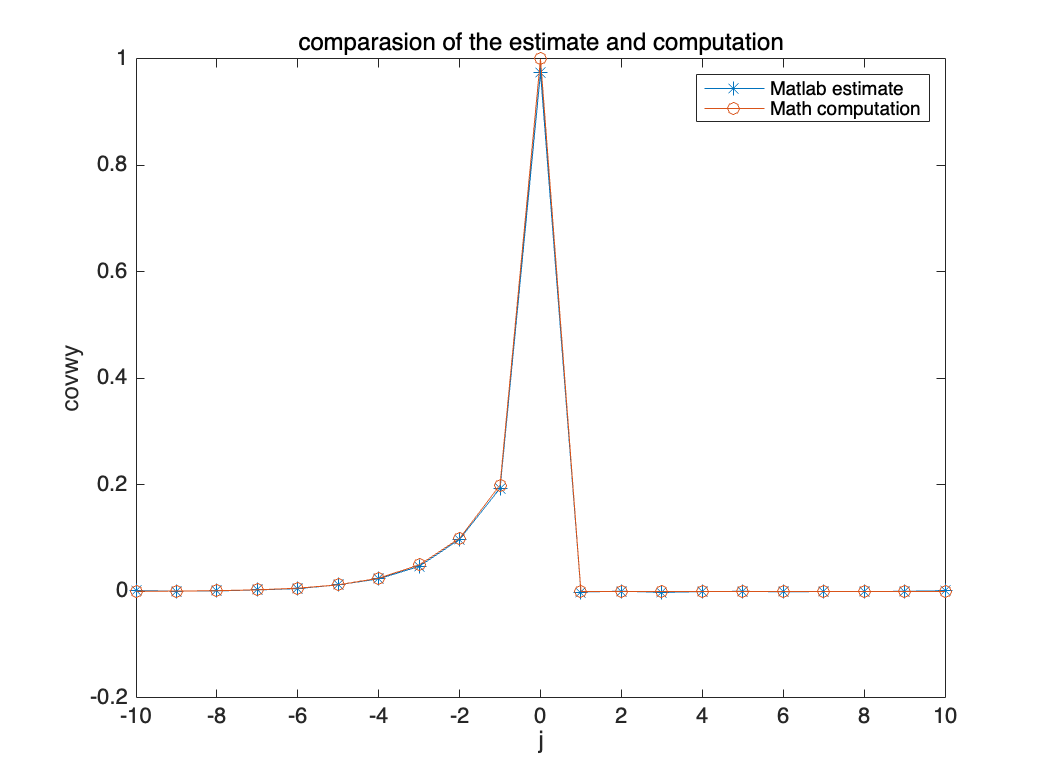



figure()
plot(l,m_cov_wy,'-*')
hold on
plot(l,f_cov_wy,'-o')
legend('Matlab estimate','Math computation');
xlabel('j');
ylabel('covwy');
title('comparasion of the estimate and computation');



% 对于l < 0，f(l)已经是0，无需额外操作
% 
% % 绘制离散时间序列图
% stem(l, f);
% xlabel('时间（l）');
% ylabel('幅值');
% title('离散时间序列 f(l)');
% 
% % 添加图例说明
% legend('f(l)');
